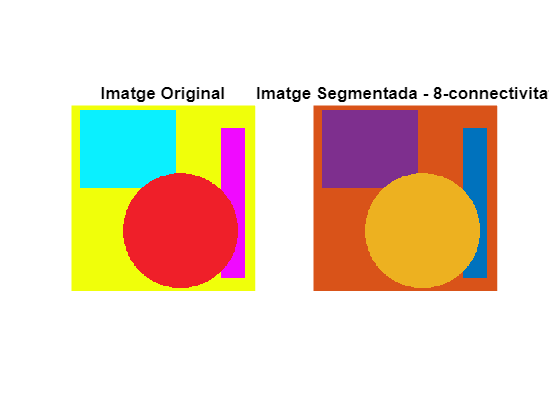

% PRACTICA 2: Segmentació d’imatges RGB mitjançant creixement de regió amb distància euclidiana

% Iniciem un comptador de temps per mesurar el temps total de còmput
tic

% Llegim la imatge
imatge = imread('color.tif');

% Comprovem si la imatge és en escala de grisos (1 sola capa)
if size(imatge, 3) ~= 3
    error('La imatge ha de ser en color (RGB). No es pot fer segmentació RGB amb una imatge en escala de grisos.');
end

% Convertim la imatge a tipus double per poder fer càlculs amb decimals.
% NOTA: No normalitza la imatge, només permet operacions amb decimals per càlculs precisos.
matriu = double(imatge);

% Inicialitzem la matriu de resultat amb zeros (només 2D, una etiqueta per píxel)
Resultat = zeros(size(matriu, 1), size(matriu, 2));

% Inicialitzem etiqueta i llindar
etiqueta = 1;
th = 25;

% Tipus de connectivitat (4 o 8)
Conectivitat = 8;  % ← pots canviar-ho aquí

% Utilitzem una cua estàtica (prealocada) per evitar el cost de redimensionar arrays en temps d'execució, guanyant eficiència en memòria i velocitat
mida_cua = size(matriu, 1) * size(matriu, 2);
vector_x = zeros(mida_cua, 1);
vector_y = zeros(mida_cua, 1);

% Busquem el primer píxel no etiquetat
[x, y] = find(Resultat == 0, 1);
if isempty(x) || isempty(y)
    error('No s''ha trobat cap píxel sense etiquetar.');
end

% Bucle principal: mentre quedin píxels sense etiquetar
while ~isempty(x)
    % Inicialitzem la mitjana RGB i sumatoris
    mitjana1 = matriu(x, y, 1);
    mitjana2 = matriu(x, y, 2);
    mitjana3 = matriu(x, y, 3);

    sumatori1 = mitjana1;
    sumatori2 = mitjana2;
    sumatori3 = mitjana3;

    comptador = 1;
    Resultat(x, y) = etiqueta;

    % Inicialitzem la cua amb el píxel inicial
    inici = 1;
    final = 1;
    vector_x(final) = x;
    vector_y(final) = y;

    % Definim els offsets segons la connectivitat triada
    if Conectivitat == 4
        offsets = [ -1,  0;   % Esquerra
                     0,  1;   % Dalt
                     1,  0;   % Dreta
                     0, -1];  % Baix
    elseif Conectivitat == 8
        offsets = [ -1,  0;    % Esquerra
                   -1,  1;    % Diagonal superior esquerra
                    0,  1;    % Dalt
                    1,  1;    % Diagonal superior dreta
                    1,  0;    % Dreta
                    1, -1;    % Diagonal inferior dreta
                    0, -1;    % Baix
                   -1, -1];   % Diagonal inferior esquerra
    else
        error('El valor de Conectivitat ha de ser 4 o 8.');
    end

    % Inici del creixement de regió
    while (inici <= final)
        % 'inici' indica el pròxim píxel a processar
        % 'final' indica on afegim nous píxels a la cua
        x1 = vector_x(inici);
        y1 = vector_y(inici);
        inici = inici + 1;

        for i = 1:size(offsets, 1)
            pixel_x = x1 + offsets(i, 1);
            pixel_y = y1 + offsets(i, 2);

            % Comprovem que estem dins dels límits de la imatge
            if (pixel_x > 0 && pixel_x <= size(matriu, 1) && pixel_y > 0 && pixel_y <= size(matriu, 2))
                if (Resultat(pixel_x, pixel_y) == 0)
                    % Calculem la distància euclidiana entre el color actual i la mitjana RGB
                    distancia = sqrt( ...
                        (matriu(pixel_x, pixel_y, 1) - mitjana1)^2 + ...
                        (matriu(pixel_x, pixel_y, 2) - mitjana2)^2 + ...
                        (matriu(pixel_x, pixel_y, 3) - mitjana3)^2 );

                    if distancia < th
                        % Etiquetem i afegim a la cua
                        Resultat(pixel_x, pixel_y) = etiqueta;

                        final = final + 1;
                        vector_x(final) = pixel_x;
                        vector_y(final) = pixel_y;

                        % Actualitzem sumatoris i mitjanes
                        sumatori1 = sumatori1 + matriu(pixel_x, pixel_y, 1);
                        sumatori2 = sumatori2 + matriu(pixel_x, pixel_y, 2);
                        sumatori3 = sumatori3 + matriu(pixel_x, pixel_y, 3);
                        comptador = comptador + 1;

                        mitjana1 = sumatori1 / comptador;
                        mitjana2 = sumatori2 / comptador;
                        mitjana3 = sumatori3 / comptador;
                    end
                end
            end
        end
    end

    % Busquem un nou píxel no etiquetat per començar una nova regió
    [x, y] = find(Resultat == 0, 1);
    if isempty(x) || isempty(y)
        break;
    end
    etiqueta = etiqueta + 1;
end

% Convertim les etiquetes a una imatge de colors per visualitzar les regions segmentades
matriu_final = label2rgb(Resultat, lines(max(Resultat(:))), 'b', 'shuffle');

% Mostrem els resultats
figure;
subplot(1, 2, 1), imshow(imatge), title('Imatge Original');
subplot(1, 2, 2), imshow(matriu_final), title(['Imatge Segmentada - ', num2str(Conectivitat), '-connectivitat']);


% Mostrem el temps total de segmentació
toc

Elapsed time is 0.444258 seconds.
